# DEMO for Corrosion Fatigue Simulation using 3-stage model

Simulation with random sampled stress ranges

clear; close all; clc; format compact; format long;
% cd 'E:\Projects\1_Living Projects\2022 CF of Bridges\Progress\mcodes';      % Path of Codes
addpath(genpath(pwd));
set(0,'defaultfigurecolor','w');

## 0. Stress range sampling from stress spectra

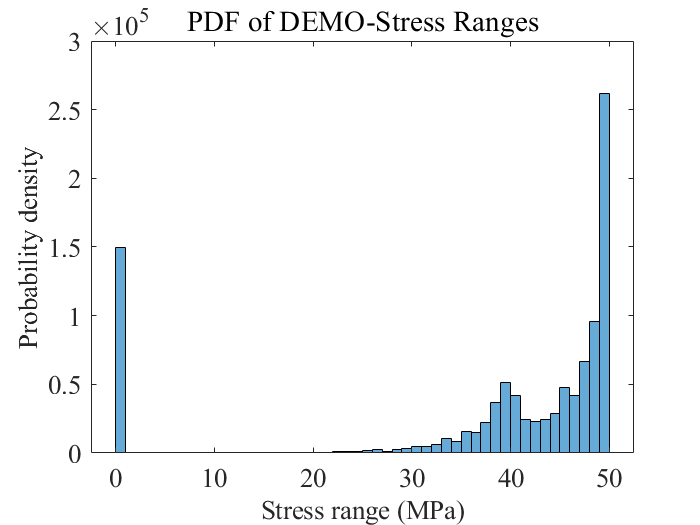

dStrAR = load('dStrEqv[DEMO_CF]');                   % Array Storing for Stress ranges
dStrAR = dStrAR.dStrE;

histogram(dStrAR,50);                               % Plot the histogram of Stress Ranges
set(gca,'fontname','Times New Roman','fontsize',16,'LineWidth',0.2);
xlabel('Stress range (MPa)','fontsize',16,'fontname','Times New Roman');
ylabel('Probability density','fontsize',16,'fontname','Times New Roman');
title('PDF of DEMO-Stress Ranges');

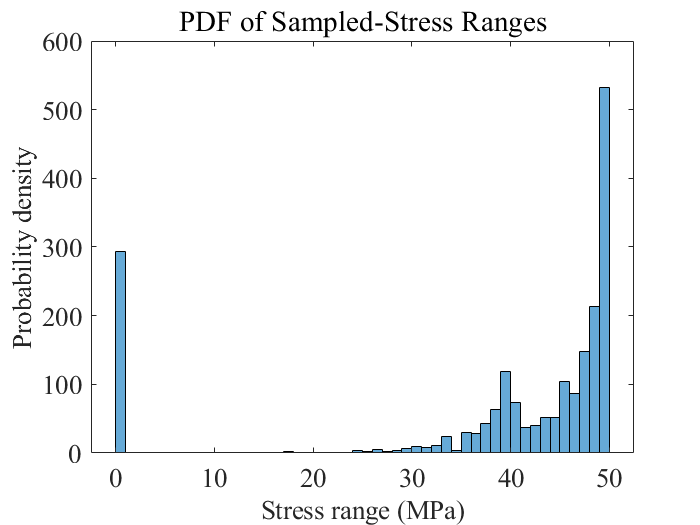


num_sam = 2000;                                         % number of samples
dStr_sam = dStrAR(randperm(length(dStrAR),num_sam)');   % Sampling
histogram(dStr_sam,50);                                 % Plot the histogram of Sampled Stress Ranges
set(gca,'fontname','Times New Roman','fontsize',16,'LineWidth',0.2);
xlabel('Stress range (MPa)','fontsize',16,'fontname','Times New Roman');
ylabel('Probability density','fontsize',16,'fontname','Times New Roman');
title('PDF of Sampled-Stress Ranges');

## 1. Stage 1 - Effective Crack Initiation under Corrosion & Fatigue (summation)

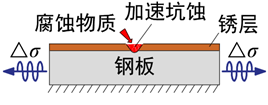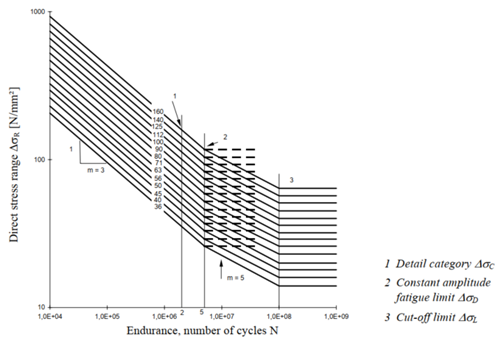


$$
\left( \frac{dD}{dt} \right)_{CF1} = \frac{{dD}_{cor}}{dt} + \frac{{dD}_{fat}}{dt} = \frac{1}{dt} \bullet \left( \frac{a}{a_{i}} \right)_{cor} + \frac{1}{dt}\left( {\sum_{i}\left. \frac{N_{i}}{\left\lbrack N_{i} \right\rbrack} \right)} \right._{fat}$$


D = Damage Factor (0.3 for initiation); t = time; cor/fat = corrosion/fatigue

a = equivalent (corrosion pit) crack depth; ai = effective depth after crack initiation; 

[Ni] = crack initiation life allowance for stress block dσi; Ni cycles by dσi

Dfat = damage solved from fatigue; Dcor = damage sovled from corrosion


$$D_{fat} = {\sum_{i}{\left( \frac{{\mathrm{\Delta}\sigma}_{i}}{{\mathrm{\Delta}\sigma}_{C,D,L}} \right)^{m_{1,2,3}} \times \frac{n_{i}}{N_{C,D,L}}}}$$


$a_{cor} = Q \times t^{1/3}$, Q = 0.19 for C4 (Qingdao) for **t in years**

**Effective initial crack size to mark transition between stages 1 and 2**

$
\frac{da_{i}}{dN} = C \bullet \left( {\mathrm{\Delta}K\left( a_{i} \right) - {\mathrm{\Delta}K}_{th}} \right)^{m} = \frac{a_{i}}{N_{i}}$，in which $\mathrm{\Delta}K\left( a_{i} \right) = Y\left( a_{i} \right)\sqrt{\pi a_{i}}\mathrm{\Delta}\sigma$

f_load = 1369/24/60/60;                         % loading frequency (HZ: 1/s)
Q_cor = 0.19;                                   % pit corrosion factor (t in years)
D_int = 0.3;                                    % damage limit for crack initiation under fatigue

y2s = 365*24*60*60;                             % year-to-seconds
a_fail = 16;                                    % size of fatigue failure (mm)

m1 = 3; m2 = 5; m3 = 22;                        % Power index for Stage 1,2,3
FATc = 100;                                     % FAT 100 for Rib-to-deck Joint
FATd = (2/5)^(1/m1) * FATc;                     % FAT at 5 million
FATt = (5/100)^(1/m2) * FATd;                   % FAT Threshold at 100 Million

C_fcg = 5.21e-13;                               % FCG rate in air
cor_fcg = 1+(Q_cor/0.19)*0.5;                   % FCG rate improvement by corrosion (1.5 for C4)
m_fcg = 3;                                      % Power index
dKth = 63;                                      % Fatigue threshold: N/mm^(3/2)

StrR = 0;                                       % Stress Ratio

dStrAR_D1 = sum((dStrAR(dStrAR>FATd)./FATd).^m1)/5e6...
    + sum((dStrAR(dStrAR<=FATd & dStrAR>FATt)./FATd).^m2)/5e6...
    + sum((dStrAR(dStrAR<FATt)./FATt).^m3)/100e6;               % Total Equivalent Damge by Spectra
dStrAR_Neff = length(dStrAR)/dStrAR_D1;                         % Equivalent Life Allowance for the Spectra
dStrEqv = (dStrAR_Neff<5e6)*((5e6/dStrAR_Neff).^(1/m1).*FATd)...
    + (dStrAR_Neff>5e6 & dStrAR_Neff<100e6)*(5e6/dStrAR_Neff).^(1/m2).*FATd...
    + (dStrAR_Neff>100e6)*(100e6/dStrAR_Neff).^(1/m3).*FATt;    % Equivalent Stress Range
fprintf("Damage Equivalent Stress Range for the spectra = %6.2f\n",dStrEqv);

Damage Equivalent Stress Range for the spectra =  43.94



D_sam = sum((dStr_sam(dStr_sam>FATc)/FATc).^m1./2e6);
D_sam = D_sam + sum((dStr_sam(dStr_sam>FATt & dStr_sam<=FATd)/FATd).^m2./5e6);
D_sam = D_sam + sum((dStr_sam(dStr_sam<=FATt)/FATt).^m3./100e6);
dDfa_2_dN = D_sam/num_sam;                      % Equivalent fatigue damage per cycle
dDfa_2_dt = f_load.*dDfa_2_dN*y2s;              % Equivalent fatigue damage per year


N_eff = 1/dDfa_2_dN;                            % effetive initiation cycles (FAT)
if N_eff < 2e6
    dStr_eqv = (2e6/(N_eff)*FATc.^m1).^(1/m1);
elseif N_eff >= 5e6 && N_eff < 100e6
    dStr_eqv = (5e6/N_eff*FATd.^m2).^(1/m2);
elseif N_eff > 100e6
    dStr_eqv = (100e6/N_eff*FATt.^m3).^(1/m3);
end
fprintf("Damage Equivalent Stress Range for the samples = %6.2f\n",dStr_eqv);

Damage Equivalent Stress Range for the samples =  44.24



N_int = D_int/dDfa_2_dN;                        % crack initiation cycles (FAT)
Y_fcg = 1.20;                                   % correction factor for FCG
Fun_a_int = @(a_int) (C_fcg.*((Y_fcg.*sqrt(pi*a_int).*dStr_eqv - dKth)/(1-StrR)).^m_fcg - a_int./N_int)./(a_int./N_int);
% a_int = fsolve(Fun_a_int,1);                    % solve effective flaw size by iteration (equal growth rate)
a_int = (dKth/FATt/Y_fcg)^2/pi;                 % direct solution using EIFS
% a_int = (dKth/dStr_eqv/Y_fcg)^2/pi;             % direct solution using EIFS

dmg_t = @(t) dDfa_2_dt.*t./D_int + Q_cor.*(t).^(1/3)/a_int - 1;
t_int = fsolve(dmg_t,0.1);                      % crack initiation life (in years)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>


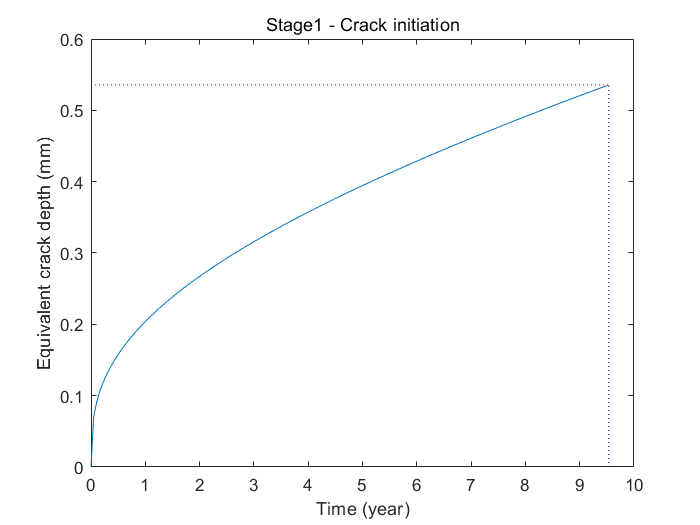


t_his = (0:0.05:floor(t_int))';                 % History of time steps
t_his = unique([t_his;t_int]);
a_his = (dmg_t(t_his)+1).*a_int;                % History of crack depth (estimated by damage)
CGR_fat = ones(size(t_his)).*dDfa_2_dt;         % History of crack growth rate under fatigue
CGR_cor = Q_cor.*t_his.^(-2/3)/3;               % History of crack growth rate under corrosion

plot(t_his,a_his); hold on;
plot([0,t_int],[a_int,a_int],'r:');
plot([t_int,t_int],[0,a_int],'b:');
hold off;
xlabel("Time (year)"); ylabel("Equivalent crack depth (mm)");
title('Stage1 - Crack initiation');

fprintf('crack initiation costs %8.2f years\n',t_int);

crack initiation costs     9.53 years


## 2. Stage 2 - Corrosion Fatigue Competition

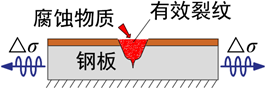


$$\left( \frac{dD}{dt} \right)_{CF2} = max\left\{ \left( \frac{da}{dt} \right)_{cor},\left( {f \bullet \frac{da}{dN}} \right)_{fat} \right\}$$



$$\left( \frac{da}{dt} \right)_{cor} = \frac{d\left( Q \bullet t^{1/3} \right)}{dt} = \frac{1}{3}Q \bullet t^{- 2/3}$$



$$\left( {f \bullet \frac{da}{dN}} \right)_{fat} = f \bullet C \bullet \left( {\mathrm{\Delta}K\left( a_{t} \right) - {\mathrm{\Delta}K}_{th}} \right)^{m}$$


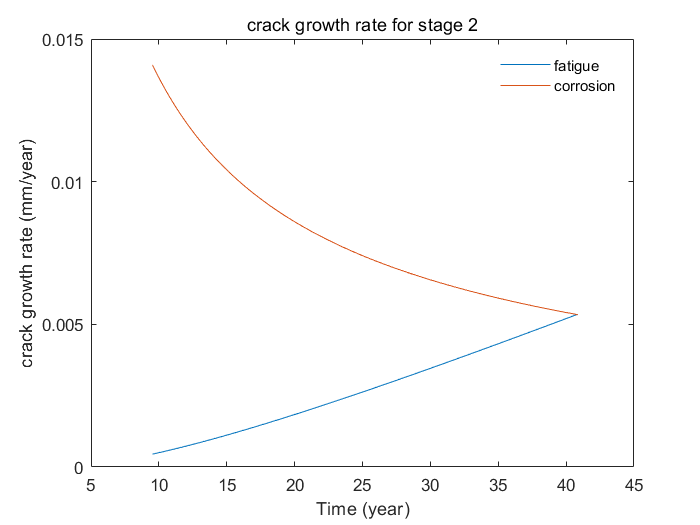

da_lim = 1e-3;                                  % limit for crack size update
t_cur = t_int;                                  % current time for stage 2 (years)
a_t = a_int;                                    % start (initial) crack size

dK_t = Y_fcg*sqrt(pi*a_t).*dStr_sam;            % dK under sampled stress ranges
da2dt_fat = sum(C_fcg*cor_fcg*((dK_t(dK_t>dKth)-dKth)./(1-StrR)).^m_fcg)/num_sam*f_load*y2s;
CGR_fat(end) = da2dt_fat;
% da/dt under fatigue using sampled stress ranges (in year)
da2dt_cor = Q_cor*t_cur.^(-2/3)/3;              % da/dt under corrosion (in year)
CGR_cor(end) = da2dt_cor;

while da2dt_fat < da2dt_cor
    dt = da_lim./da2dt_cor;
    t_cur = t_cur + dt;
    t_his = [t_his;t_cur];
    a_t = a_t + da_lim;
    a_his = [a_his;a_t];
    
    dK_t = Y_fcg*sqrt(pi*a_t).*dStr_sam;            % dK under sampled stress ranges
    da2dt_fat = sum(C_fcg*cor_fcg*((dK_t(dK_t>dKth)-dKth)./(1-StrR)).^m_fcg)/num_sam*f_load*y2s;
    CGR_fat = [CGR_fat;da2dt_fat];
    % da/dt under fatigue using sampled stress ranges (in year)
    da2dt_cor = Q_cor*t_cur.^(-2/3)/3;              % da/dt under corrosion (in year)
    CGR_cor = [CGR_cor;da2dt_cor];
    
    if a_t > a_fail
        break;
    end
end

t_compe = t_cur;                                    % Ending time for stage 2 (in year)
plot(t_his(t_his>=t_int),CGR_fat(t_his>=t_int),t_his(t_his>=t_int),CGR_cor(t_his>=t_int));
xlabel("Time (year)"); ylabel("crack growth rate (mm/year)");
title('crack growth rate for stage 2');
legend({'fatigue','corrosion'},"Box","off");

fprintf('corrosion-fatigue competition costs %8.2f years\n',t_compe - t_int);

corrosion-fatigue competition costs    31.32 years


## 3. Stage 3 - Corrosion-assisted Fatigue

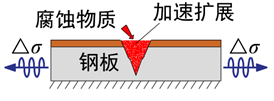


$$\left( \frac{dD}{dt} \right)_{CF2} = \left( \frac{da}{f \bullet dN} \right)_{fat} = \frac{1}{f}C \bullet \left( {\mathrm{\Delta}K\left( a_{t} \right) - {\mathrm{\Delta}K}_{th}} \right)^{m}$$


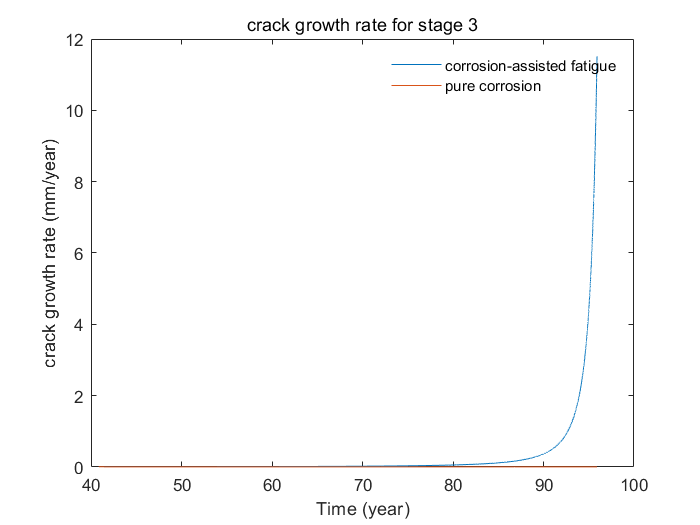


while a_t < a_fail
    dK_t = Y_fcg*sqrt(pi*a_t).*dStr_sam;            % dK under sampled stress ranges
    da2dt_fat = sum(C_fcg*cor_fcg*((dK_t(dK_t>dKth)-dKth)./(1-StrR)).^m_fcg)/num_sam*f_load*y2s;
    CGR_fat = [CGR_fat;da2dt_fat];
    da2dt_cor = Q_cor*t_cur.^(-2/3)/3;              % da/dt under corrosion (in year)
    CGR_cor = [CGR_cor;da2dt_cor];
    
    dt = da_lim./da2dt_fat;
    t_cur = t_cur + dt;
    t_his = [t_his;t_cur];
    a_t = a_t + da_lim;
    a_his = [a_his;a_t];
end

t_sum = t_cur;                                      % Total corrosion fatigue life
plot(t_his(t_his>=t_compe),CGR_fat(t_his>=t_compe),t_his(t_his>=t_compe),CGR_cor(t_his>=t_compe));
xlabel("Time (year)"); ylabel("crack growth rate (mm/year)");
title('crack growth rate for stage 3');
legend({'corrosion-assisted fatigue','pure corrosion'},"Box","off");

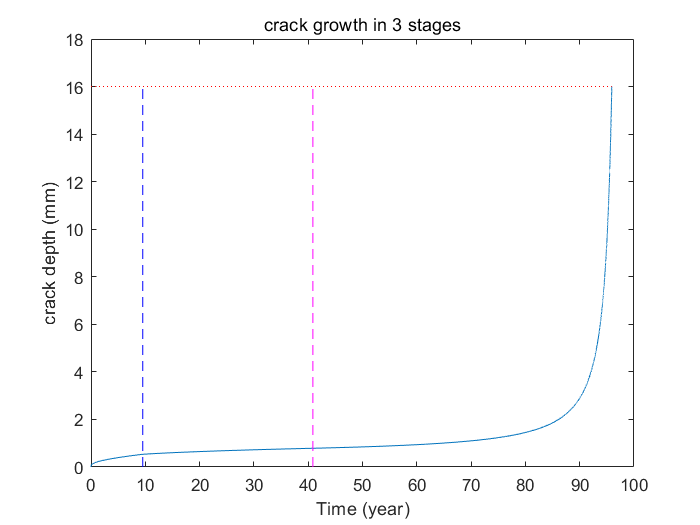


plot(t_his,a_his);
hold on;
plot([0,t_sum],[a_fail,a_fail],'r:');
plot([t_int,t_int],[0,a_fail],'b--');
plot([t_compe,t_compe],[0,a_fail],'m--');
xlabel("Time (year)"); ylabel("crack depth (mm)");
title('crack growth in 3 stages');
hold on;

fprintf(['CF Life: Stage 1 (%6.2f) + Stage 2 (%6.2f) + Stage 3 (%6.2f) = %6.2f years in total\n' ...
    'Stage 1: Stage 2: Stage 3 = %6.1f:%6.1f:%6.1f\n'], t_int, t_compe-t_int, t_sum - t_compe, t_sum, ...
    t_int/t_sum*100,(t_compe-t_int)/t_sum*100, (t_sum-t_compe)/t_sum*100);  % Result of corrosion fatigue life

CF Life: Stage 1 (  9.53) + Stage 2 ( 31.32) + Stage 3 ( 55.06) =  95.91 years in total
Stage 1: Stage 2: Stage 3 =    9.9:  32.7:  57.4
